AvCL_ss = readtable('AvCL_ss');
Av_ss = table2array(AvCL_ss(1:1201,2));

AvCL_tt = readtable('AvCL_tt');
Av_tt = table2array(AvCL_tt(1:1201,2));

AvCL_ff = readtable('AvCL_ff');
Av_ff = table2array(AvCL_ff(1:1201,2));

df_raw = readtable('AvCL_ss');
f = table2array(df_raw(1:1201,1));

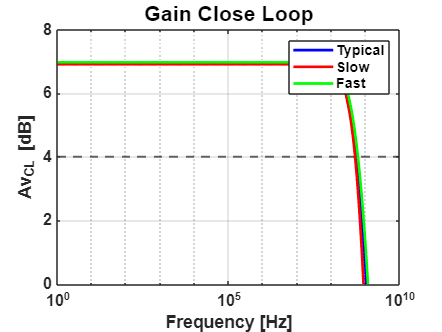

figure;

semilogx(f, Av_tt,'b', LineWidth=2)
hold on;
semilogx(f, Av_ss, 'r', LineWidth=2)
semilogx(f, Av_ff, 'g', LineWidth=2)

xlabel('Frequency [Hz]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica','FontWeight','bold','FontUnits','points');
ylabel('Av_{CL} [dB]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica','FontWeight','bold','FontUnits','points');
ylim([0 8]);
ax = gca; % obtiene el eje actual
ax.FontWeight = 'bold';
ax.FontSize = 12;
yline(4, '--', 'LineWidth', 1.5);
grid on;
legend('Typical', 'Slow', 'Fast')
title('Gain Close Loop','FontSize',16);

GRAFICAS OPEN LOOP

AvOL_tt = readtable('AvOL_tt');
AvOL_tt = table2array(AvOL_tt(1:12001,2));

AvOL_ss = readtable('AvOL_ss');
AvOL_ss = table2array(AvOL_ss(1:12001,2));

AvOL_ff = readtable('AvOL_ff');
AvOL_ff = table2array(AvOL_ff(1:12001,2));

PhaseOL_tt = readtable('PhaseOL_tt');
PhaseOL_tt = table2array(PhaseOL_tt(1:12001,2));

PhaseOL_ss = readtable('PhaseOL_ss');
PhaseOL_ss = table2array(PhaseOL_ss(1:12001,2));

PhaseOL_ff = readtable('PhaseOL_ff');
PhaseOL_ff = table2array(PhaseOL_ff(1:12001,2));

df = readtable('AvOL_tt');                           % vector de frecuencia
f_o = table2array(df(1:12001,1));


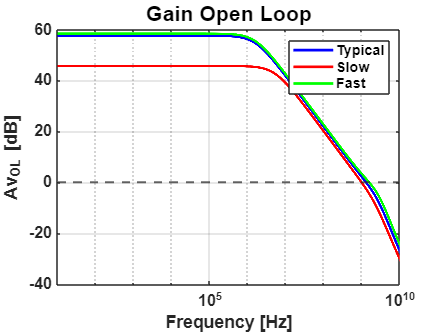

figure;

semilogx(f_o, AvOL_tt,'b', LineWidth=2)
hold on;
semilogx(f_o, AvOL_ss, 'r', LineWidth=2)
semilogx(f_o, AvOL_ff, 'g', LineWidth=2)

xlabel('Frequency [Hz]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
ylabel('Av_{OL} [dB]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
% ylim([0 8]);
xlim([10e0 1e10]);
yline(0, '--', 'LineWidth', 1.5);
grid on;
ax = gca; % obtiene el eje actual
ax.FontWeight = 'bold';
ax.FontSize = 12;
legend('Typical', 'Slow', 'Fast')
title('Gain Open Loop','FontSize',16);

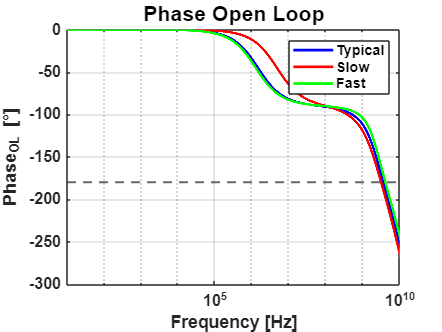


figure;
semilogx(f_o, PhaseOL_tt,'b', LineWidth=2)
hold on;
semilogx(f_o, PhaseOL_ss,'r', LineWidth=2)
semilogx(f_o, PhaseOL_ff,'g', LineWidth=2)
xlabel('Frequency [Hz]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
ylabel('Phase_{OL} [°]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
yline(-180, '--', 'LineWidth', 1.5);
grid on;
ax = gca; % obtiene el eje actual
ax.FontWeight = 'bold';
ax.FontSize = 12;
xlim([10e0 1e10]);
legend('Typical', 'Slow', 'Fast')
title('Phase Open Loop','FontSize',16);

hold off;

FFT

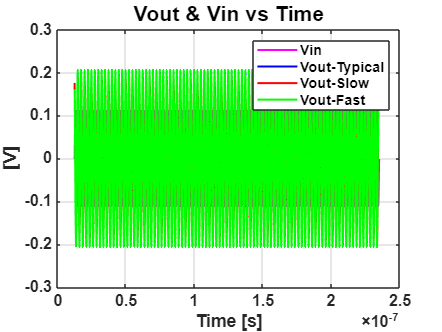

Vin = readtable('Vin');
t_400 = table2array(Vin(20480:364544+20479,1));
Vin = table2array(Vin(20480:364544+20479,2));


plot(t_400,Vin,'m', 'LineWidth', 1.5)
hold on

Vout_tt = readtable('Vout_tt');
Vout_tt = table2array(Vout_tt(20480:364544+20479,2));

Vout_ss = readtable('Vout_ss');
Vout_ss = table2array(Vout_ss(20480:364544+20479,2));

Vout_ff = readtable('Vout_ff');
Vout_ff = table2array(Vout_ff(20480:364544+20479,2));

plot(t_400,Vout_tt, 'b', 'LineWidth', 1.5)
plot(t_400,Vout_ss, 'r', 'LineWidth', 1.5)
plot(t_400,Vout_ff, 'g', 'LineWidth', 1.5)

xlabel('Time [s]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
ylabel('[V]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');

grid on;
ax = gca; % obtiene el eje actual
ax.FontWeight = 'bold';
ax.FontSize = 12;
% xlim([10e0 1e10]);
legend('Vin','Vout-Typical', 'Vout-Slow', 'Vout-Fast')
title('Vout & Vin vs Time','FontSize',16);

hold off


fs_400 = 1/(t_400(2)-t_400(1));     % Frecuencia de muestreo (Hz) 

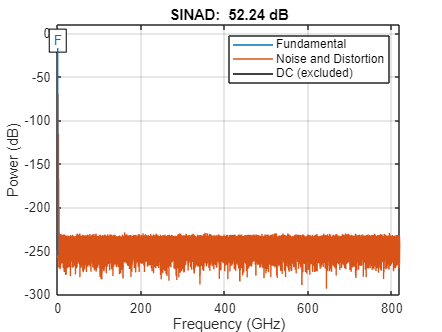

sinad(Vout_tt, fs_400);

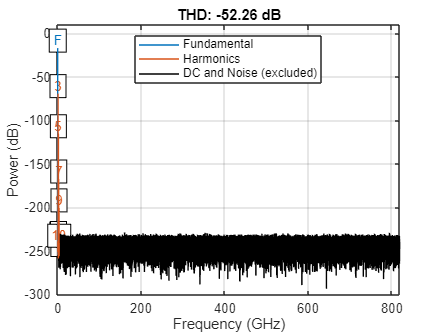

thd(Vout_tt,fs_400,10,"aliased");

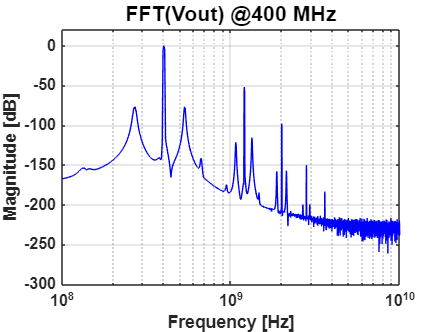



N_tt = length(Vout_tt);
x_win_tt = Vout_tt .* hann(N_tt);          % Aplicar ventana para reducir leakage
X_tt = fft(x_win_tt,N_tt);
X_mag_tt = abs(X_tt(1:N_tt/2));          % Magnitud de la mitad positiva
X_db_tt = 20*log10(X_mag_tt / max(X_mag_tt)); % Normalización a 0 dB
f_tt = (0:N_tt/2-1)*(fs_400/N_tt);           % Eje de frecuencia

figure;
plot(f_tt, X_db_tt, 'b'); grid on;

xlabel('Frequency [Hz]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
ylabel('Magnitude [dB]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
grid on;
ax = gca; % obtiene el eje actual
ax.FontWeight = 'bold';
ax.FontSize = 12;
xlim([1e8,1e10]);
ylim([-300 20])
% % legend('Typical', 'Slow', 'Fast')
title('FFT(Vout) @400 MHz','FontSize',16);
set(gca, 'XScale', 'log');

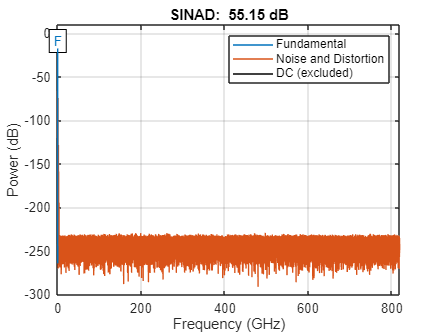



sinad(Vout_ss, fs_400);

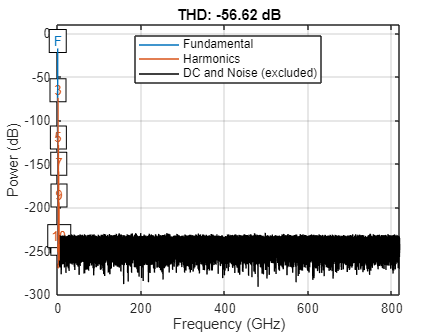

thd(Vout_ss,fs_400,10,"aliased");

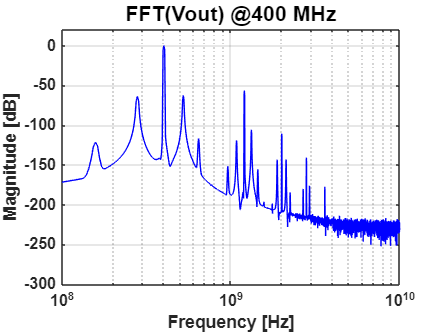



N_ss = length(Vout_ss);
x_win_ss = Vout_ss .* hann(N_ss);          % Aplicar ventana para reducir leakage
X_ss = fft(x_win_ss,N_ss);
X_mag_ss = abs(X_ss(1:N_ss/2));          % Magnitud de la mitad positiva
X_db_ss = 20*log10(X_mag_ss / max(X_mag_ss)); % Normalización a 0 dB
f_ss = (0:N_ss/2-1)*(fs_400/N_ss);           % Eje de frecuencia

figure;
plot(f_ss, X_db_ss, 'b'); grid on;

xlabel('Frequency [Hz]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
ylabel('Magnitude [dB]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
grid on;
ax = gca; % obtiene el eje actual
ax.FontWeight = 'bold';
ax.FontSize = 12;
xlim([1e8,1e10]);
ylim([-300 20])
% % legend('Typical', 'Slow', 'Fast')
title('FFT(Vout) @400 MHz','FontSize',16);
set(gca, 'XScale', 'log');

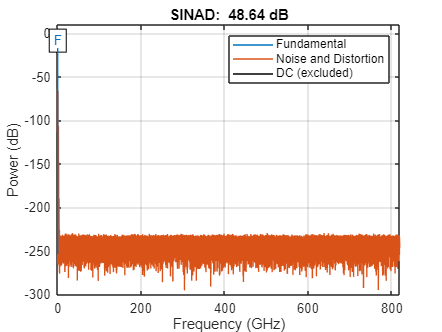



sinad(Vout_ff, fs_400);

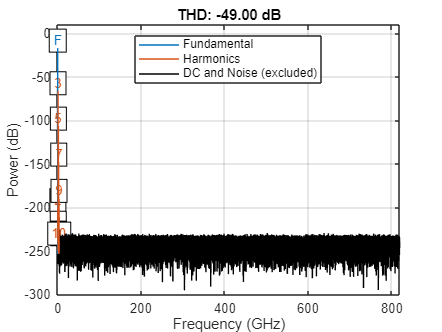

thd(Vout_ff,fs_400,10,"aliased");

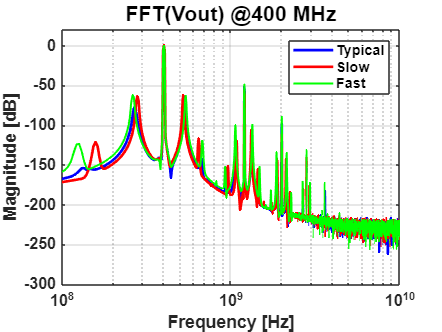



N_ff = length(Vout_ff);
x_win_ff = Vout_ff .* hann(N_ff);          % Aplicar ventana para reducir leakage
X_ff = fft(x_win_ff,N_ff);
X_mag_ff = abs(X_ff(1:N_ff/2));          % Magnitud de la mitad positiva
X_db_ff = 20*log10(X_mag_ff / max(X_mag_ff)); % Normalización a 0 dB
f_ff = (0:N_ff/2-1)*(fs_400/N_ff);           % Eje de frecuencia

figure;
plot(f_tt, X_db_tt, 'b', LineWidth=2); grid on;
hold on;
plot(f_ss, X_db_ss, 'r', LineWidth=2); grid on;
plot(f_ff, X_db_ff, 'g', LineWidth=1.5); grid on;
xlabel('Frequency [Hz]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
ylabel('Magnitude [dB]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
grid on;
ax = gca; % obtiene el eje actual
ax.FontWeight = 'bold';
ax.FontSize = 12;
xlim([1e8,1e10]);
ylim([-300 20])
legend('Typical', 'Slow', 'Fast')
title('FFT(Vout) @400 MHz','FontSize',16);
set(gca, 'XScale', 'log');
hold off;

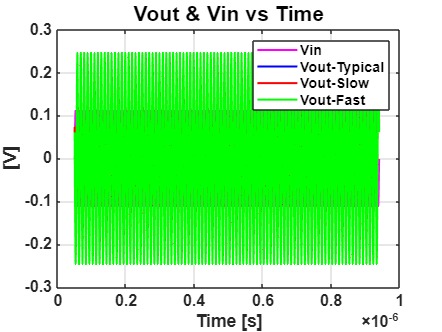

Vin_ = readtable('Vin_1');
t_100 = table2array(Vin_(20480:364544+20479,1));
Vin_ = table2array(Vin_(20480:364544+20479,2));


plot(t_100,Vin_,'m', 'LineWidth', 1.5)
hold on

Vout_tt_1 = readtable('Vout_tt_1');
Vout_tt_1 = table2array(Vout_tt_1(20480:364544+20479,2));

Vout_ss_1 = readtable('Vout_ss_1');
Vout_ss_1 = table2array(Vout_ss_1(20480:364544+20479,2));

Vout_ff_1 = readtable('Vout_ff_1');
Vout_ff_1 = table2array(Vout_ff_1(20480:364544+20479,2));

plot(t_100,Vout_tt_1, 'b', 'LineWidth', 1.5)
plot(t_100,Vout_ss_1, 'r', 'LineWidth', 1.5)
plot(t_100,Vout_ff_1, 'g', 'LineWidth', 1.5)

xlabel('Time [s]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
ylabel('[V]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');

grid on;
ax = gca; % obtiene el eje actual
ax.FontWeight = 'bold';
ax.FontSize = 12;
% xlim([10e0 1e10]);
legend('Vin','Vout-Typical', 'Vout-Slow', 'Vout-Fast')
title('Vout & Vin vs Time','FontSize',16);

hold off


fs_100 = 1/(t_100(2)-t_100(1));     % Frecuencia de muestreo (Hz) 

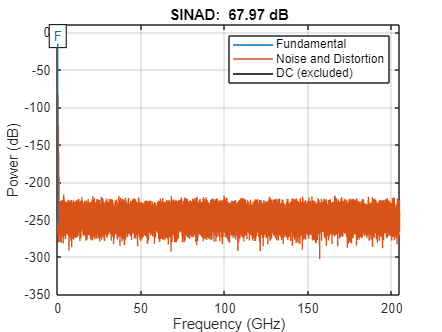

sinad(Vout_tt_1, fs_100);

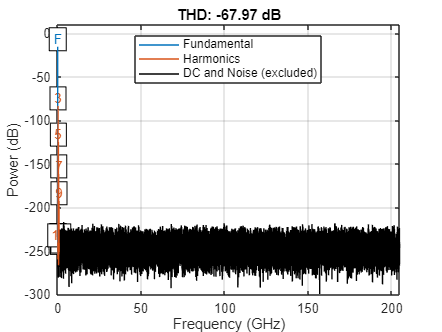

thd(Vout_tt_1,fs_100,10,"aliased");

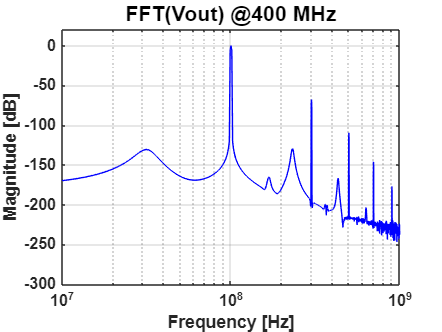



N_tt_1 = length(Vout_tt_1);
x_win_tt_1 = Vout_tt_1 .* hann(N_tt_1);          % Aplicar ventana para reducir leakage
X_tt_1 = fft(x_win_tt_1,N_tt_1);
X_mag_tt_1 = abs(X_tt_1(1:N_tt_1/2));          % Magnitud de la mitad positiva
X_db_tt_1 = 20*log10(X_mag_tt_1 / max(X_mag_tt_1)); % Normalización a 0 dB
f_tt_1 = (0:N_tt_1/2-1)*(fs_100/N_tt_1);           % Eje de frecuencia

figure;
plot(f_tt_1, X_db_tt_1, 'b'); grid on;

xlabel('Frequency [Hz]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
ylabel('Magnitude [dB]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
grid on;
ax = gca; % obtiene el eje actual
ax.FontWeight = 'bold';
ax.FontSize = 12;
xlim([1e7,1e9]);
ylim([-300 20])
% % legend('Typical', 'Slow', 'Fast')
title('FFT(Vout) @400 MHz','FontSize',16);
set(gca, 'XScale', 'log');

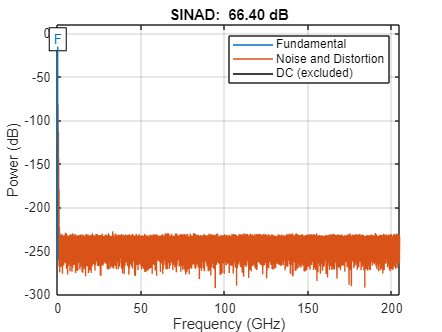




sinad(Vout_ss_1, fs_100);

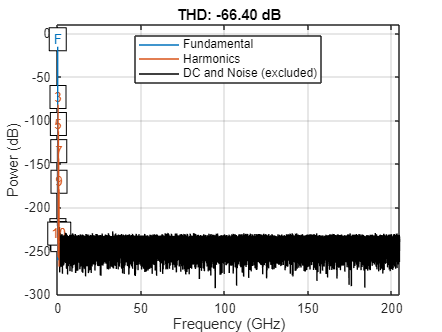

thd(Vout_ss_1,fs_100,10,"aliased");

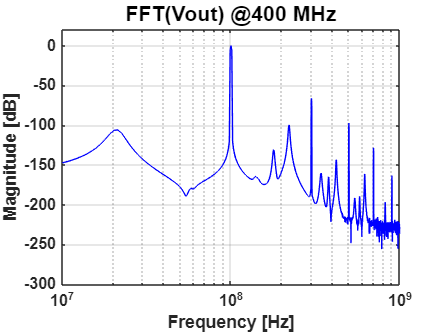



N_ss_1 = length(Vout_ss_1);
x_win_ss_1 = Vout_ss_1 .* hann(N_ss_1);          % Aplicar ventana para reducir leakage
X_ss_1 = fft(x_win_ss_1,N_ss_1);
X_mag_ss_1 = abs(X_ss_1(1:N_ss_1/2));          % Magnitud de la mitad positiva
X_db_ss_1 = 20*log10(X_mag_ss_1 / max(X_mag_ss_1)); % Normalización a 0 dB
f_ss_1 = (0:N_ss_1/2-1)*(fs_100/N_ss_1);           % Eje de frecuencia

figure;
plot(f_ss_1, X_db_ss_1, 'b'); grid on;

xlabel('Frequency [Hz]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
ylabel('Magnitude [dB]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
grid on;
ax = gca; % obtiene el eje actual
ax.FontWeight = 'bold';
ax.FontSize = 12;
xlim([1e7,1e9]);
ylim([-300 20])
% % legend('Typical', 'Slow', 'Fast')
title('FFT(Vout) @400 MHz','FontSize',16);
set(gca, 'XScale', 'log');

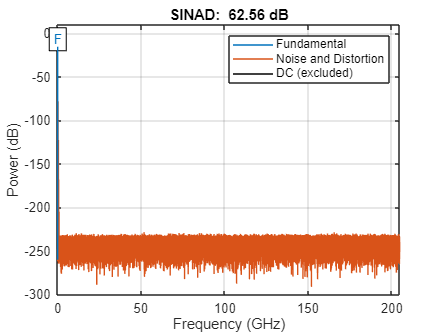




sinad(Vout_ff_1, fs_100);

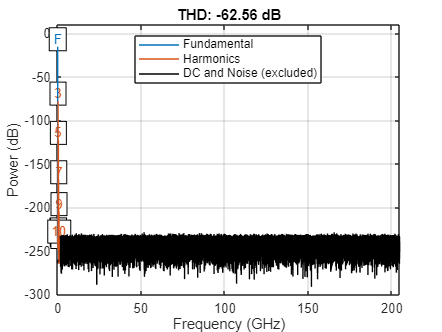

thd(Vout_ff_1,fs_100,10,"aliased");

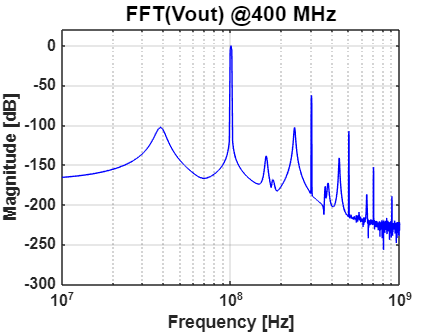



N_ff_1 = length(Vout_ff_1);
x_win_ff_1 = Vout_ff_1 .* hann(N_ff_1);          % Aplicar ventana para reducir leakage
X_ff_1 = fft(x_win_ff_1,N_ff_1);
X_mag_ff_1 = abs(X_ff_1(1:N_ff_1/2));          % Magnitud de la mitad positiva
X_db_ff_1 = 20*log10(X_mag_ff_1 / max(X_mag_ff_1)); % Normalización a 0 dB
f_ff_1 = (0:N_ff_1/2-1)*(fs_100/N_ff_1);           % Eje de frecuencia

figure;
plot(f_ff_1, X_db_ff_1, 'b'); grid on;

xlabel('Frequency [Hz]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
ylabel('Magnitude [dB]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
grid on;
ax = gca; % obtiene el eje actual
ax.FontWeight = 'bold';
ax.FontSize = 12;
xlim([1e7,1e9]);
ylim([-300 20])
% % legend('Typical', 'Slow', 'Fast')
title('FFT(Vout) @400 MHz','FontSize',16);
set(gca, 'XScale', 'log');

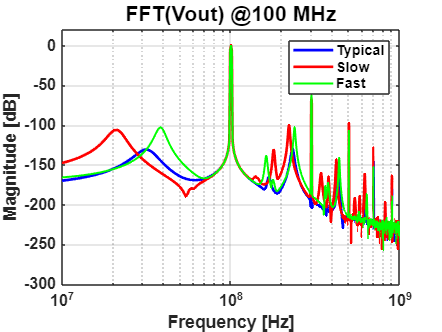




figure;
plot(f_tt_1, X_db_tt_1, 'b', LineWidth=2); grid on;
hold on;
plot(f_ss_1, X_db_ss_1, 'r', LineWidth=2); grid on;
plot(f_ff_1, X_db_ff_1, 'g', LineWidth=1.5); grid on;
xlabel('Frequency [Hz]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
ylabel('Magnitude [dB]','FontSize',16, 'FontWeight', 'bold','FontName','Helvetica');
grid on;
ax = gca; % obtiene el eje actual
ax.FontWeight = 'bold';
ax.FontSize = 12;
xlim([1e7,1e9]);
ylim([-300 20])
legend('Typical', 'Slow', 'Fast')
title('FFT(Vout) @100 MHz','FontSize',16);
set(gca, 'XScale', 'log');
hold off;